# Diseño de un sistema regulador con observador de estados de orden mínimo

% Ejemplo seccion 10-6 Texto Ogata. Diseño de sistemas reguladores con
% observadores
clear
close all
num=[10 20]

num =     10    20


den=conv([1 4 0],[1 6])

den =      1    10    24     0


[A,B,C,D]=tf2ss(num,den)

A =    -10   -24     0
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0    10    20


D = 0

J = [-1+1i*2 -1-1i*2 -5]

J =   -1.0000 + 2.0000i  -1.0000 - 2.0000i  -5.0000 + 0.0000i


sys_ol=ss(A,B,C,D);

## Prueba de controlabilidad

sys_ord=order(sys_ol)

sys_ord = 3

rank_sys=rank(ctrb(A,B))

rank_sys = 3

det(ctrb(A,B))

ans = 1

## Prueba de observabilidad

rank_sys=rank(obsv(sys_ol))

rank_sys = 3

det_sys=det(obsv(sys_ol))

det_sys = -16000

## Obtención de la matriz de realimentación de los estados K

K = acker(A,B,J)

K =     -3    -9    25


% Obtaining the observer gain matrix Ke
% Ver ecuaciones 10-81 y 10-82
Aaa = 0; Aab = [1 0]; Aba = [0;0]; Abb = [0 1;-24 -10]

Abb =      0     1
   -24   -10


Ba = 0; Bb = [10;-80];
L = [-10 -10]

L =    -10   -10


## Obtención de la matriz de ganancias Ke para el observador

Ke = acker(Abb',Aab',L)'

Ke =     10
   -24


## Obtencion de la función de transferencia del controlador-observador

Ka=K(1);
Kb=K(2:3);
Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);
% Ecuacion 10-109

### Con la función ss2tf de MATLAB

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num = 1.0e+03 *

   -0.6930   -6.7440   -0.3000


den = 1.0e+04 *

    0.0001   -0.2070   -2.0080


Gcobs1=tf(num,den)

Gcobs1 =
 
  -693 s^2 - 6744 s - 300
  -----------------------
  s^2 - 2070 s - 2.008e04
 
Continuous-time transfer function.
Model Properties


### En forma simbólica

syms s
% Ecuacion 10-108
sys1=-(Ctilde*inv(s*eye(size(Atilde,1))-Atilde)*Btilde+Dtilde);
Gcobss=simplify(sys1)

$$Gcobss = \frac{3\,\left(231\,s^{2}+2248\,s+100\right)}{-s^{2}+2070\,s+20080}$$

pole(Gcobs1)

ans = 1.0e+03 *

    2.0797
   -0.0097


#### Observación: el sistema es inestable en lazo abierto

## Cálculo de la ecuación característica 

### Mediante MATLAB

[num1,den1] = ss2tf(A-B*K,eye(3),eye(3),eye(3),1);
[num2,den2] = ss2tf(Abb-Ke*Aab,eye(2),eye(2),eye(2),1);
charact_eq = conv(den1,den2)

charact_eq = 1.0e+03 *

    0.0010    0.0270    0.2550    1.0250    2.0000    2.5000


roots(charact_eq)

ans =  -10.0000 + 0.0000i
 -10.0000 + 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


### En forma simbólica

syms s
charact_eqs=det(s*eye(size(A,1))-A+B*K)*det(s*eye(size(Abb,1))-Abb+Ke*Aab)

$$charact\_eqs = {\left(s+10\right)}^{2}\,\left(s^{3}+7\,s^{2}+15\,s+25\right)$$

roots(conv([1 20 100],[1 7 15 25]))

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


#### Observación: el sistema es estable en lazo cerrado

## Segunda prueba:

### Modificando  los polos deseados para el observador de orden mínimo 

L = [-4.5 -4.5]

L =    -4.5000   -4.5000


Ke = acker(Abb',Aab',L)'

Ke =    -1.0000
    6.2500


Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);

## Obtencion de la función de transferencia del controlador-observador

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num =   162.2500  606.7500  -60.7500


den = 1.0e+03 *

    0.0010   -2.0810   -5.7222


Gcobs2=tf(num,den)

Gcobs2 =
 
  162.2 s^2 + 606.8 s - 60.75
  ---------------------------
      s^2 - 2081 s - 5722
 
Continuous-time transfer function.
Model Properties


pole(Gcobs2)

ans = 1.0e+03 *

    2.0837
   -0.0027


## Obtención de la respuesta del sistema a condiciones iniciales

% Ecuaciones 10-110 y 10-111 (10-94)
AA = [A-B*K B*Kb; zeros(2,3) Abb-Ke*Aab]

AA =    -7.0000  -15.0000  -25.0000   -9.0000   25.0000
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0         0    1.0000    1.0000
         0         0         0  -30.2500  -10.0000


sys = ss(AA,eye(5),eye(5),eye(5));
t = 0:0.01:8;
x0=[1;0;0;1;0]   % vector de condiciones iniciales

x0 =      1
     0
     0
     1
     0


x = initial(sys,x0,t)

x =     1.0000         0         0    1.0000         0
    0.8085    0.0091    0.0000    1.0086   -0.2892
    0.5615    0.0160    0.0002    1.0145   -0.5529
    0.2692    0.0202    0.0004    1.0179   -0.7929
   -0.0592    0.0212    0.0006    1.0190   -1.0107
   -0.4153    0.0189    0.0008    1.0181   -1.2078
   -0.7919    0.0129    0.0009    1.0153   -1.3855
   -1.1822    0.0030    0.0010    1.0108   -1.5453
   -1.5805   -0.0108    0.0010    1.0047   -1.6884
   -1.9816   -0.0286    0.0008    0.9971   -1.8158


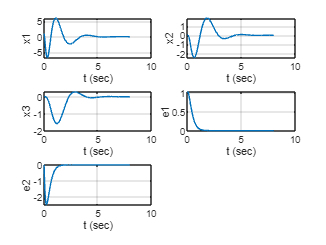

x1 = [1 0 0 0 0]*x';
x2 = [0 1 0 0 0]*x';
x3 = [0 0 1 0 0]*x';
e1 = [0 0 0 1 0]*x';
e2 = [0 0 0 0 1]*x';
figure(1000)
subplot(3,2,1); plot(t,x1); grid
xlabel ('t (sec)'); ylabel('x1')
subplot(3,2,2); plot(t,x2); grid
xlabel ('t (sec)'); ylabel('x2')
subplot(3,2,3); plot(t,x3); grid
xlabel ('t (sec)'); ylabel('x3')
subplot(3,2,4); plot(t,e1); grid
xlabel('t (sec)'); ylabel('e1')
subplot(3,2,5); plot(t,e2); grid
xlabel('t (sec)'); ylabel('e2')

## Diagramas del Bode del sistema regulador diseñado

numol=10*[1 2];
denol=conv([1 4 0],[1 6]);
Gsol=tf(numol,denol)

Gsol =
 
       10 s + 20
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


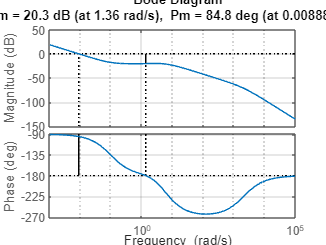

figure(1)
margin(Gsol*Gcobs2)
grid

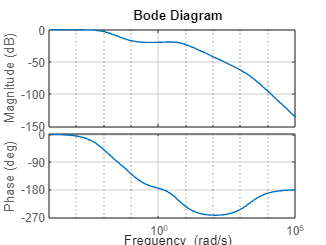

figure(2)
bode(feedback(Gsol*Gcobs2,1))
grid

## Root Locus del sistema regulador con polos del observador en s=-10 y s=-10

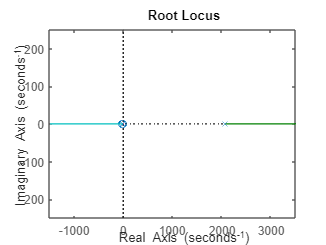

figure(3)
rlocus(Gsol*Gcobs1)

Gsol*Gcobs1

ans =
 
         -6930 s^3 - 8.13e04 s^2 - 1.379e05 s - 6000
  ---------------------------------------------------------
  s^5 - 2060 s^4 - 4.076e04 s^3 - 2.505e05 s^2 - 4.819e05 s
 
Continuous-time transfer function.
Model Properties


## Root Locus del sistema regulador con polos del observador en s=-4.5 y s=-4.5

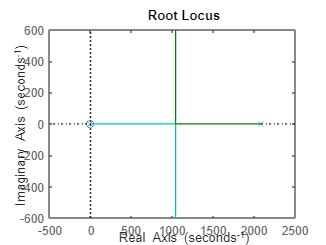

figure(4)
rlocus(Gsol*Gcobs2)

Gsol*Gcobs2

ans =
 
           1622 s^3 + 9313 s^2 + 1.153e04 s - 1215
  ---------------------------------------------------------
  s^5 - 2071 s^4 - 2.651e04 s^3 - 1.072e05 s^2 - 1.373e05 s
 
Continuous-time transfer function.
Model Properties
